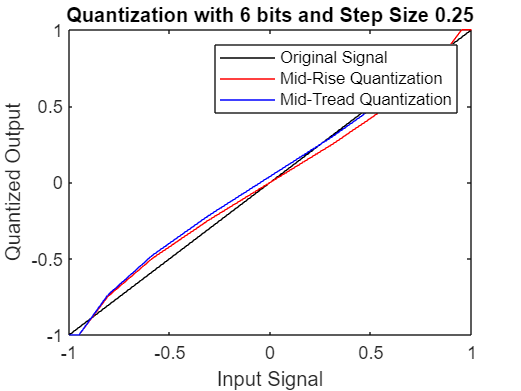

% Example
f=5;
fs=2*f;
t=0:0.01:1;
input_signal = sin(2*pi*f*t);
num_bits = 6;
step_size = 0.25; % Change this to your desired step size

quantized_midrise = midRiseQuantization(input_signal, num_bits, step_size);
quantized_midtread = midTreadQuantization(input_signal, num_bits, step_size);

figure;
plot(input_signal, input_signal, '-k', input_signal, quantized_midrise, 'r', input_signal, quantized_midtread, 'b');
legend('Original Signal', 'Mid-Rise Quantization', 'Mid-Tread Quantization');
xlabel('Input Signal');
ylabel('Quantized Output');
title(['Quantization with ', num2str(num_bits), ' bits and Step Size ', num2str(step_size)]);


% Function for mid-rise quantization

function quantized_signal = midRiseQuantization(input_signal, num_bits, step_size)
    quantization_levels = -1:step_size:1;
    quantized_signal = interp1(quantization_levels, quantization_levels, input_signal, 'nearest');
end

% Function for mid-tread quantization
function quantized_signal = midTreadQuantization(input_signal, num_bits, step_size)
    quantization_levels = -1:step_size+0.01:1;
    quantized_signal = interp1(quantization_levels, quantization_levels, input_signal, 'nearest');
end
